# Fast Poisson Equation Solver using DCT

Copyright 2020 The MathWorks, Inc.

## Introduction

This document describes the FFT based fast solver of the Poisson equation of the form:


$$\frac{\partial ^2 u}{\partial x^2} + \frac{\partial ^2 u}{\partial y^2} = f(x,y)$$


Here we suppose the simple grid and the 2nd order finite difference scheme.


$$\frac{u(i-1,j) - 2 u(i,j) + u(i+1,j)}{\Delta x^2}
+
\frac{u(i,j-1) - 2 u(i,j) + u(i,j+1)}{\Delta y^2}
= f(i,j)$$


This document describes two methods to solve this discretized equation for $u$. One is by directly solving the linear equations, and the other uses **D**iscrete **C**osine **T**ransform (DCT: [wiki page](https://en.wikipedia.org/wiki/Discrete_cosine_transform)). MATLAB code follows.

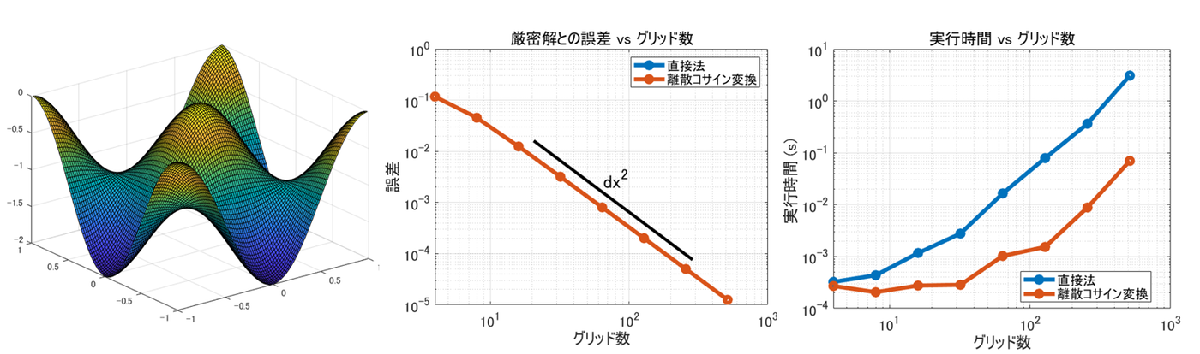

From the left: Example of a solution of a Poisson equation, numerical error from the exact solution vs. the grid number, and processing time vs. the grid number.

If you took CFD class at university, you must be familiar with this, as it appears in solving incompressible Navier-Stokes equations. Please note: Although we use FFT, this is only 2nd order, not the spectral accuracy.

### Environment 

MATLAB R2019b

Signal Processing Toolbox (`dct` [doc page](https://jp.mathworks.com/help/signal/ref/dct.html)) 

or

Image Processing Toolbox (`dct2` [doc page](https://jp.mathworks.com/help/images/ref/dct2.html))

There are two different functions to perform DCT depending on if it's one dimension or two dimensions, and they are in different toolboxes. DCT itself can be achieved by `fft` function` (`[File Exchange: dctt](https://jp.mathworks.com/matlabcentral/fileexchange/18924-dctt)) but here we used `dct2.` I leave the task of replacing it with `fft` to the reader.

## Computational Cost: Direct methods vs. DCT based

Solving partial differential equation sounds scary, but after descritazation it's a just a set of linear equations ${\bf A} {\bf u} = {\bf f} $. If you solve this by directly inverting the matrix, the cost is (in general) $\mathcal{O}(n^3)$. This means that if you double the grid number, the cost is estimated to be 4^3 = 64 times more for 2D, **8^3 = 512 times more for 3D case. **

If ${\bf A}$is static and does not change over time and one needs to solve it repetitively, you can precompute LU decomposition. This will decrease the cost but still $\mathcal{O}(n^2)$. The Iterative solver can be alternative, but here we make the use of the good nature of ${\bf A}$and diagonalize by the use of DCT. I believe the cost of FFTW is $\mathcal{O}(n \log n)$ according to their documentation. 

## Problem Setting

To easily validate the solution, we solve


$$\frac{\partial ^2 u}{\partial x^2} + \frac{\partial ^2 u}{\partial y^2} = - 2 \pi^2 \cos{(\pi x)}\cos{(\pi y)}$$


with the exact solution of 


$$u(x,y) = \cos{(\pi x)}\cos{(\pi y)}.$$


Suppose a staggered grid (see below) with $u$ is defined at the center of each grid cell. The computational domain is $-1 \le x \le 1$ and $-1 \le y \le 1$. The boundary condition is Neumann, $\partial u/\partial n = 0$. Here for the sake of simplicity, the gradient is 0, but I can be any value. In case you want to use Dirichlet BC, Discrete Sine Transform will be useful.

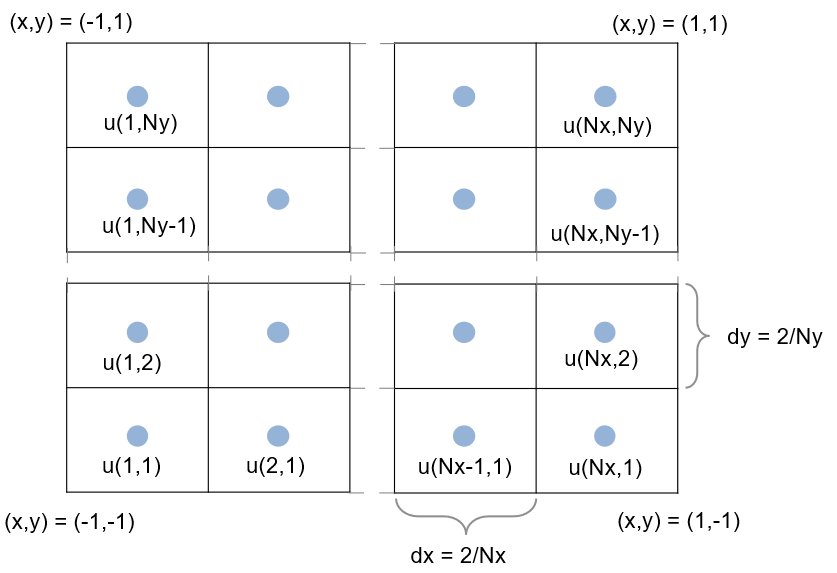

Since we are using 2nd order scheme, it helps to have one ghost cell outside of the domain as


$$\begin{array}{c}
u(0,j) = u(1,j) \\
u(i,0) = u(i,1)
\end{array}$$


we can keep the same stencil at and inside the boundary.

## Direct Method

Please note that if we express


$$\frac{u(i-1,j) - 2 u(i,j) + u(i+1,j)}{\Delta x^2}
+
\frac{u(i,j-1) - 2 u(i,j) + u(i,j+1)}{\Delta y^2}
= f(i,j)$$


as a set of linear equations ${\bf A} {\bf u} = {\bf f}$, where ${\bf A}$ is a second-order centered finite difference operator and ${\bf f}$ is a modified right-hand side accommodating the boundary conditions. ${\bf u}$ is a vector of solution


$$u(1,1), u(2,1), ..., u(Nx,1), u(1,2), ..., u(Nx,Ny).$$


If we have $N_x$ and $N_y$ grid points in x and y directions respectively, ${\bf A}$ is a matrix of $N_x N_y \times N_x N_y$, ${\bf u}$ and ${\bf f}$ are vectors of $N_x N_y \times 1$.

${\bf A}$ is sparse and is going to look like the following ($N_x = N_y = 5$, used `spy` function to draw):

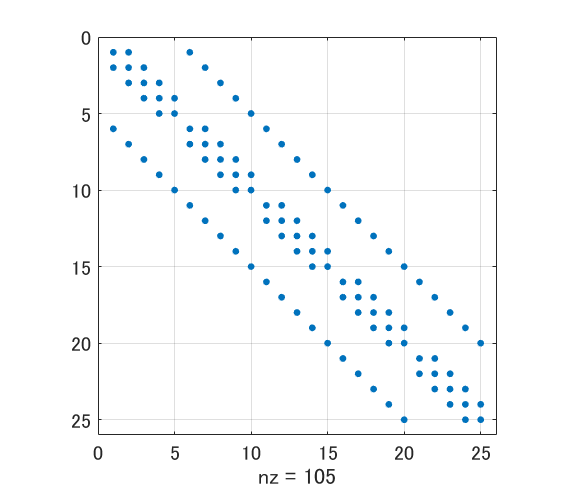

The values related to the derivative in x-direction locate next to each other, but ones from the y-derivative are a little far, and it makes the bandwidth of the matrix wider. The situation is worse in 3D as you can imagine. 

Here's the function to solve the equation: Constructing ${\bf A}$ is the most cumbersome part, but once it's built `\` (backslash) will take care of it.

## Discrete Cosine Transform Based

Here we use [REDFT10 (DCT-II)](http://www.fftw.org/fftw3_doc/1d-Real_002deven-DFTs-_0028DCTs_0029.html) defined in FFTW.


$$u(x_i, y_j) = 2 \sum_{k_i=0}^{N_x-1} \tilde{u}(k_i, y_j)  \cos{\left(\frac{\pi k_i(i+1/2)}{N_x}\right)}.$$


### Why do we need cosine transform?

We do not have periodic boundary conditions, but can we use FFT?  Here a quote from the FFTW documentation: 

Because of the even symmetry, however, the sine terms in the DFT all cancel and the remaining cosine terms are written explicitly below. This formulation often leads people to call such a transform a discrete cosine transform (DCT), although it is really just a special case of the DFT. [FFTW:1d Real-even DFTs (DCTs)](http://www.fftw.org/fftw3_doc/1d-Real_002deven-DFTs-_0028DCTs_0029.html)

The original array of data (say,{12345}) will be expanded in such a way that the extended array has an even symmetry (say, {1234554321}) and periodicity. And it helps to diagonalize the matrix ${\bf A}$ as described in detail below. FFTW has four DCTs (DCT-I to DCT-IV) for four variations of "symmetry" and these are implemented in *dct* and *dct2* of MATLAB.

### Does this work for higher-order schemes too?

Yes but not always. Here are some quate from Simens et al. (2009)

the Gibb’s errors due to the implicit derivative discontinuities at the non-periodic end points are of order dx^2

higher-order schemes in non-periodic domains cannot be treated in this (be expanded in cosines series) way, because they require boundary schemes with different modified wavenumbers than the interior operator". (Simens, M., Jim´enez, J., Hoyas, S., Mizuno, Y., 2009. A high-resolution code for turbulent boundary layers. Journal of Computational Physics.)

This is because the matrix to be solved should have boundary schemes that give the same modified wave number throughout the domain, including the boundary, which is not always the case for the higher-order scheme. However, if one recognizes the difference between the matrix solved using discrete cosine transform and the matrix that actually needs to be solved, one can overcome this issue.

### Let's apply DCT to the discrete Poisson Equation

Applying DCT in both (x and y) directions, we obtain


$$u(x_i, y_j) = 4 \sum_{k_j=0}^{N_y-1} \sum_{k_j=0}^{N_y-1} \tilde{u}(k_i, k_j)  \cos{\left(\frac{\pi k_i(i+1/2)}{N_x}\right)} \cos{\left(\frac{\pi k_j(j+1/2)}{N_y}\right)}.$$


Substituting it to the discretized equations and ***after simple algebra***, each term becomes


$$\frac{u(i-1,j) - 2 u(i,j) + u(i+1,j)}{\Delta x^2}
= \frac{4}{\Delta x^2} \sum_{k_i=0}^{N_x-1} \sum_{k_j=0}^{N_y-1} \tilde{u}(k_i, k_j) \lambda_{xj} \cos{\left(\frac{\pi k_i(i+1/2)}{N_x}\right)}  \cos{\left(\frac{\pi k_j(j+1/2)}{N_y}\right)}$$



$$\frac{u(i,j-1) - 2 u(i,j) + u(i,j+1)}{\Delta y^2}
= \frac{4}{\Delta x^2}  \sum_{k_i=0}^{N_x-1} \sum_{k_j=0}^{N_y-1} \tilde{u}(k_i, k_j) \lambda_{yi} \cos{\left(\frac{\pi k_i(i+1/2)}{N_x}\right)} \cos{\left(\frac{\pi k_j(j+1/2)}{N_y}\right)}$$


You can see clear symmetric structure. Here we define,


$$\lambda_{xi} = 2 \left( \cos\left(\frac{\pi k_i}{N_x}\right)-1 \right), \lambda_{yj} = 2 \left( \cos\left(\frac{\pi k_j}{N_y}\right)-1 \right).$$


In simplifying the equations, the relationship 


$$\frac{ \sin{(a (i+1))} - 2 \sin{(a i)} + \sin{(a (i-1))} }{\sin{ (a i)}} 
= 2 \left( \cos{ a }  - 1 \right).$$


comes in handy. Eventually, the discretized equation, 


$$\frac{u(i-1,j) - 2 u(i,j) + u(i+1,j)}{\Delta x^2}
+
\frac{u(i,j-1) - 2 u(i,j) + u(i,j+1)}{\Delta y^2}
= f(i,j)$$


finally becomes


$$\left[ \frac{\lambda_{xi}}{\Delta x^2} + \frac{\lambda_{yj}}{\Delta y^2} \right] \tilde{u}(k_i, k_j) = \tilde{f}(k_i, k_j),$$


and we get $\lambda_{xi} \times \lambda_{yj}$ of independent equations. In relation to spectoral methods, $\lambda_{xi}$ and $\lambda_{yj}
$ are also called **modified wavenumber**.

Here's the function to solve the equation with DCT: 

### Appendix: DCT in one direction only

Of course you do not have to perform 2D DCT. When you perform DCT in x-direction only,


$$\left[ \frac{\lambda_{xi}}{\Delta x^2}  + \frac{\delta^2}{\delta y^2}  \right] \tilde{u}(k_i,y_j) = \tilde{f}(k_i,y_j).$$


Finite difference in y-direction is denoted as $\delta^2/\delta y^2$ and that of x-direction $\delta^2/\delta x^2$ is now diagonalized. Here we have $k_i$ number of independent tridiagonal matrixs $\delta^2/\delta y^2$, in other words, we need to solve $\tilde{u_j} = [ u_1, u_2, \cdots, u_{ny} ]^{T} $ for each $k_i$:


$$\left[ \frac{1}{\Delta x^2} \lambda_{xi}   + \frac{\delta^2}{\delta y^2}    \right] =  \frac{1}{\Delta y^2} \left(
\begin{array}{cccccc}
 -1 &1 &&&\\
 1 & -2 & 1 && \\
  & \ddots & \ddots & \ddots &\\
  &   & 1 & -2 & 1\\
 & & &  2 & -1\\
\end{array}
\right) 
+ \frac{1}{\Delta x^2} \lambda_{xi} \bf{I} $$


The required computational cost is $\mathcal{O}(n)$ ([Wikipedia: Tridiagonal matrix](https://en.wikipedia.org/wiki/Tridiagonal_matrix)). If your problem is massive and needs to run in parallel, this strategy might fit better depending on your parallelization strategy.

## Code Validation 

Let's check if `solvePoissonEquation_direct.m` and `solvePoissonEquation_2dDCT.m` solves the equations and their computational costs.

### Do we have the right solution?

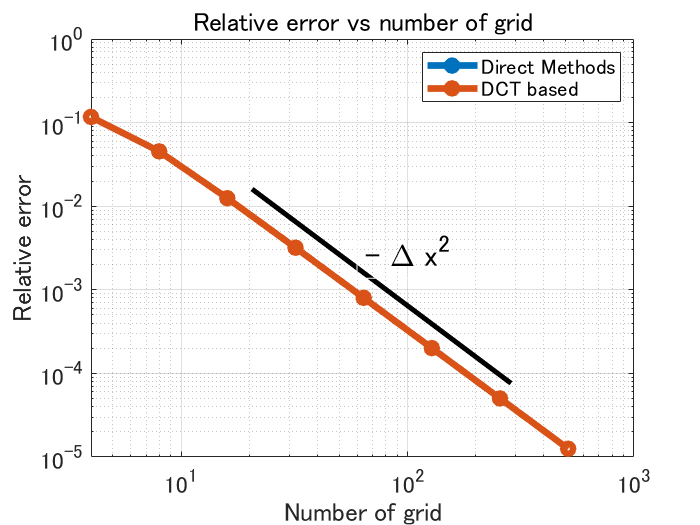

ntests = 9;
errors = zeros(ntests,2);
for ii=2:ntests
    N = 2^ii; % N = 4,8,16,...,512
    % by Direct Methods 
    [x,y,sol1] = solvePoissonEquation_direct(N,N);
    % by DCT
    [~,~,sol2] = solvePoissonEquation_2dDCT(N,N);
    
    % The exact solution
    exactsol = cos(pi*x).*cos(pi*y);
    
    % Calculate the relative error from the exact solution
    % Please note that the solution is only unique up to some constant
    % difference.
    % Neumann BC である故、定数分解がずれている
    % ものも許容されるべきなのでその分補正します。
    constShift = exactsol(1,1)-sol1(1,1);
    errors(ii,1) = norm(exactsol-constShift-sol1)/N;
    
    constShift = exactsol(1,1)-sol2(1,1);
    errors(ii,2) = norm(exactsol-constShift-sol2)/N;
end

%% Plotting the results
figure(1)
loglog(2.^(1:ntests),errors,'Marker','o','LineWidth',4)

% Minor cosmetic changes
handle_axes = gca;
handle_axes.FontSize = 14;
box(handle_axes,'on');
grid(handle_axes,'on');

% legend
legend({'Direct Methods','DCT based'});
grid on
% Textbox annotation
annotation('textbox',[0.51 0.47 0.2 0.1],...
    'String',{'- \Delta x^2'},...
    'FontSize',18,'EdgeColor',[1 1 1]);

% Line annotation
annotation('line',[0.36 0.73],[0.64 0.27],'LineWidth',3);
xlabel('Number of grid')
ylabel('Relative error')
title('Relative error vs number of grid')
hold off

As expected, you can clearly see the 2nd order regression from both schemes (yes, we are solving the exact same discretized equations.) Increasing the grid number by 10, the relative error from the exact solution becomes 1/100. Good.

### Performance?

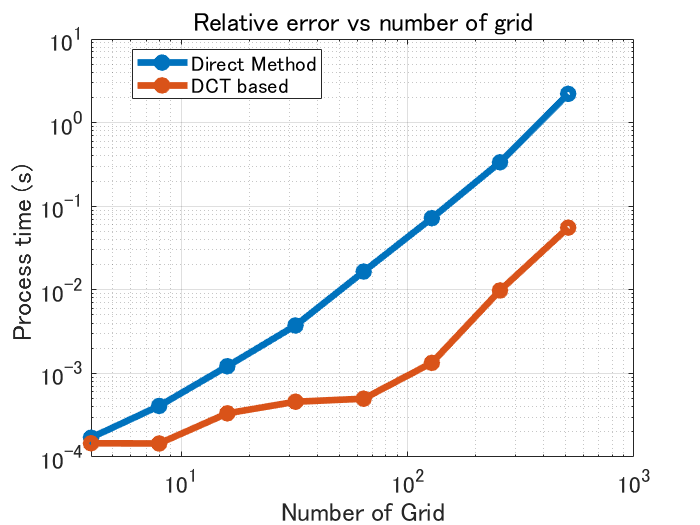

ntests = 9;
pw = 1:ntests;
times = zeros(ntests,2);
for ii=2:ntests
    N = 2^ii; % N = 4,8,16,...,512
    % by Direct Methods
    f1 = @() solvePoissonEquation_direct(N,N);
    % by DCT
    f2 = @() solvePoissonEquation_2dDCT(N,N);
    
    % timeit performs the function multiple times and returns the median
    times(ii,1) = timeit(f1,3);
    times(ii,2) = timeit(f2,3);
end

%% Plotting the results
figure(1)
loglog(2.^(1:ntests),times,'Marker','o','LineWidth',4)

% Minor cosmetic changes
handle_axes = gca;
handle_axes.FontSize = 14;
box(handle_axes,'on');
grid(handle_axes,'on');

% legend 
legend({'Direct Method','DCT based'},'Location','best');
grid on
xlabel('Number of Grid')
ylabel('Process time (s) ')
title('Relative error vs number of grid')
hold off

The method with DCT runs faster, and the Direct Methods is still about $\mathcal{O}(n^{2.2})$. Not so bad, probably thanks to MATLAB's  `\` (backslash) operators. 

## Summary

We compared the two methods for solving a Poisson Equation with Neumann BC; the direct method and the method used DCT.

Of course, DCT might not appropriate for uneven grid or the more complicated boundary conditions. But for the cases that DCT can be applied, the code becomes consise and its performance is better.